# Demo for Clustering of corr. matrices

                                                            A Riemannian Tool for Clustering of Geo-Spatial Multivariate Data

Alvaro I. Riquelme and Julian M. Ortiz

*alvaro.riquelme@queensu.ca*

## Import data

clc
clear
addpath(genpath('./DTI_SpectralQuaternion'));
addpath(genpath('./covariancetoolbox'));

db=dlmread('myData.txt',',',1,0);

### 1.4.- Scatterplot of Input Variables

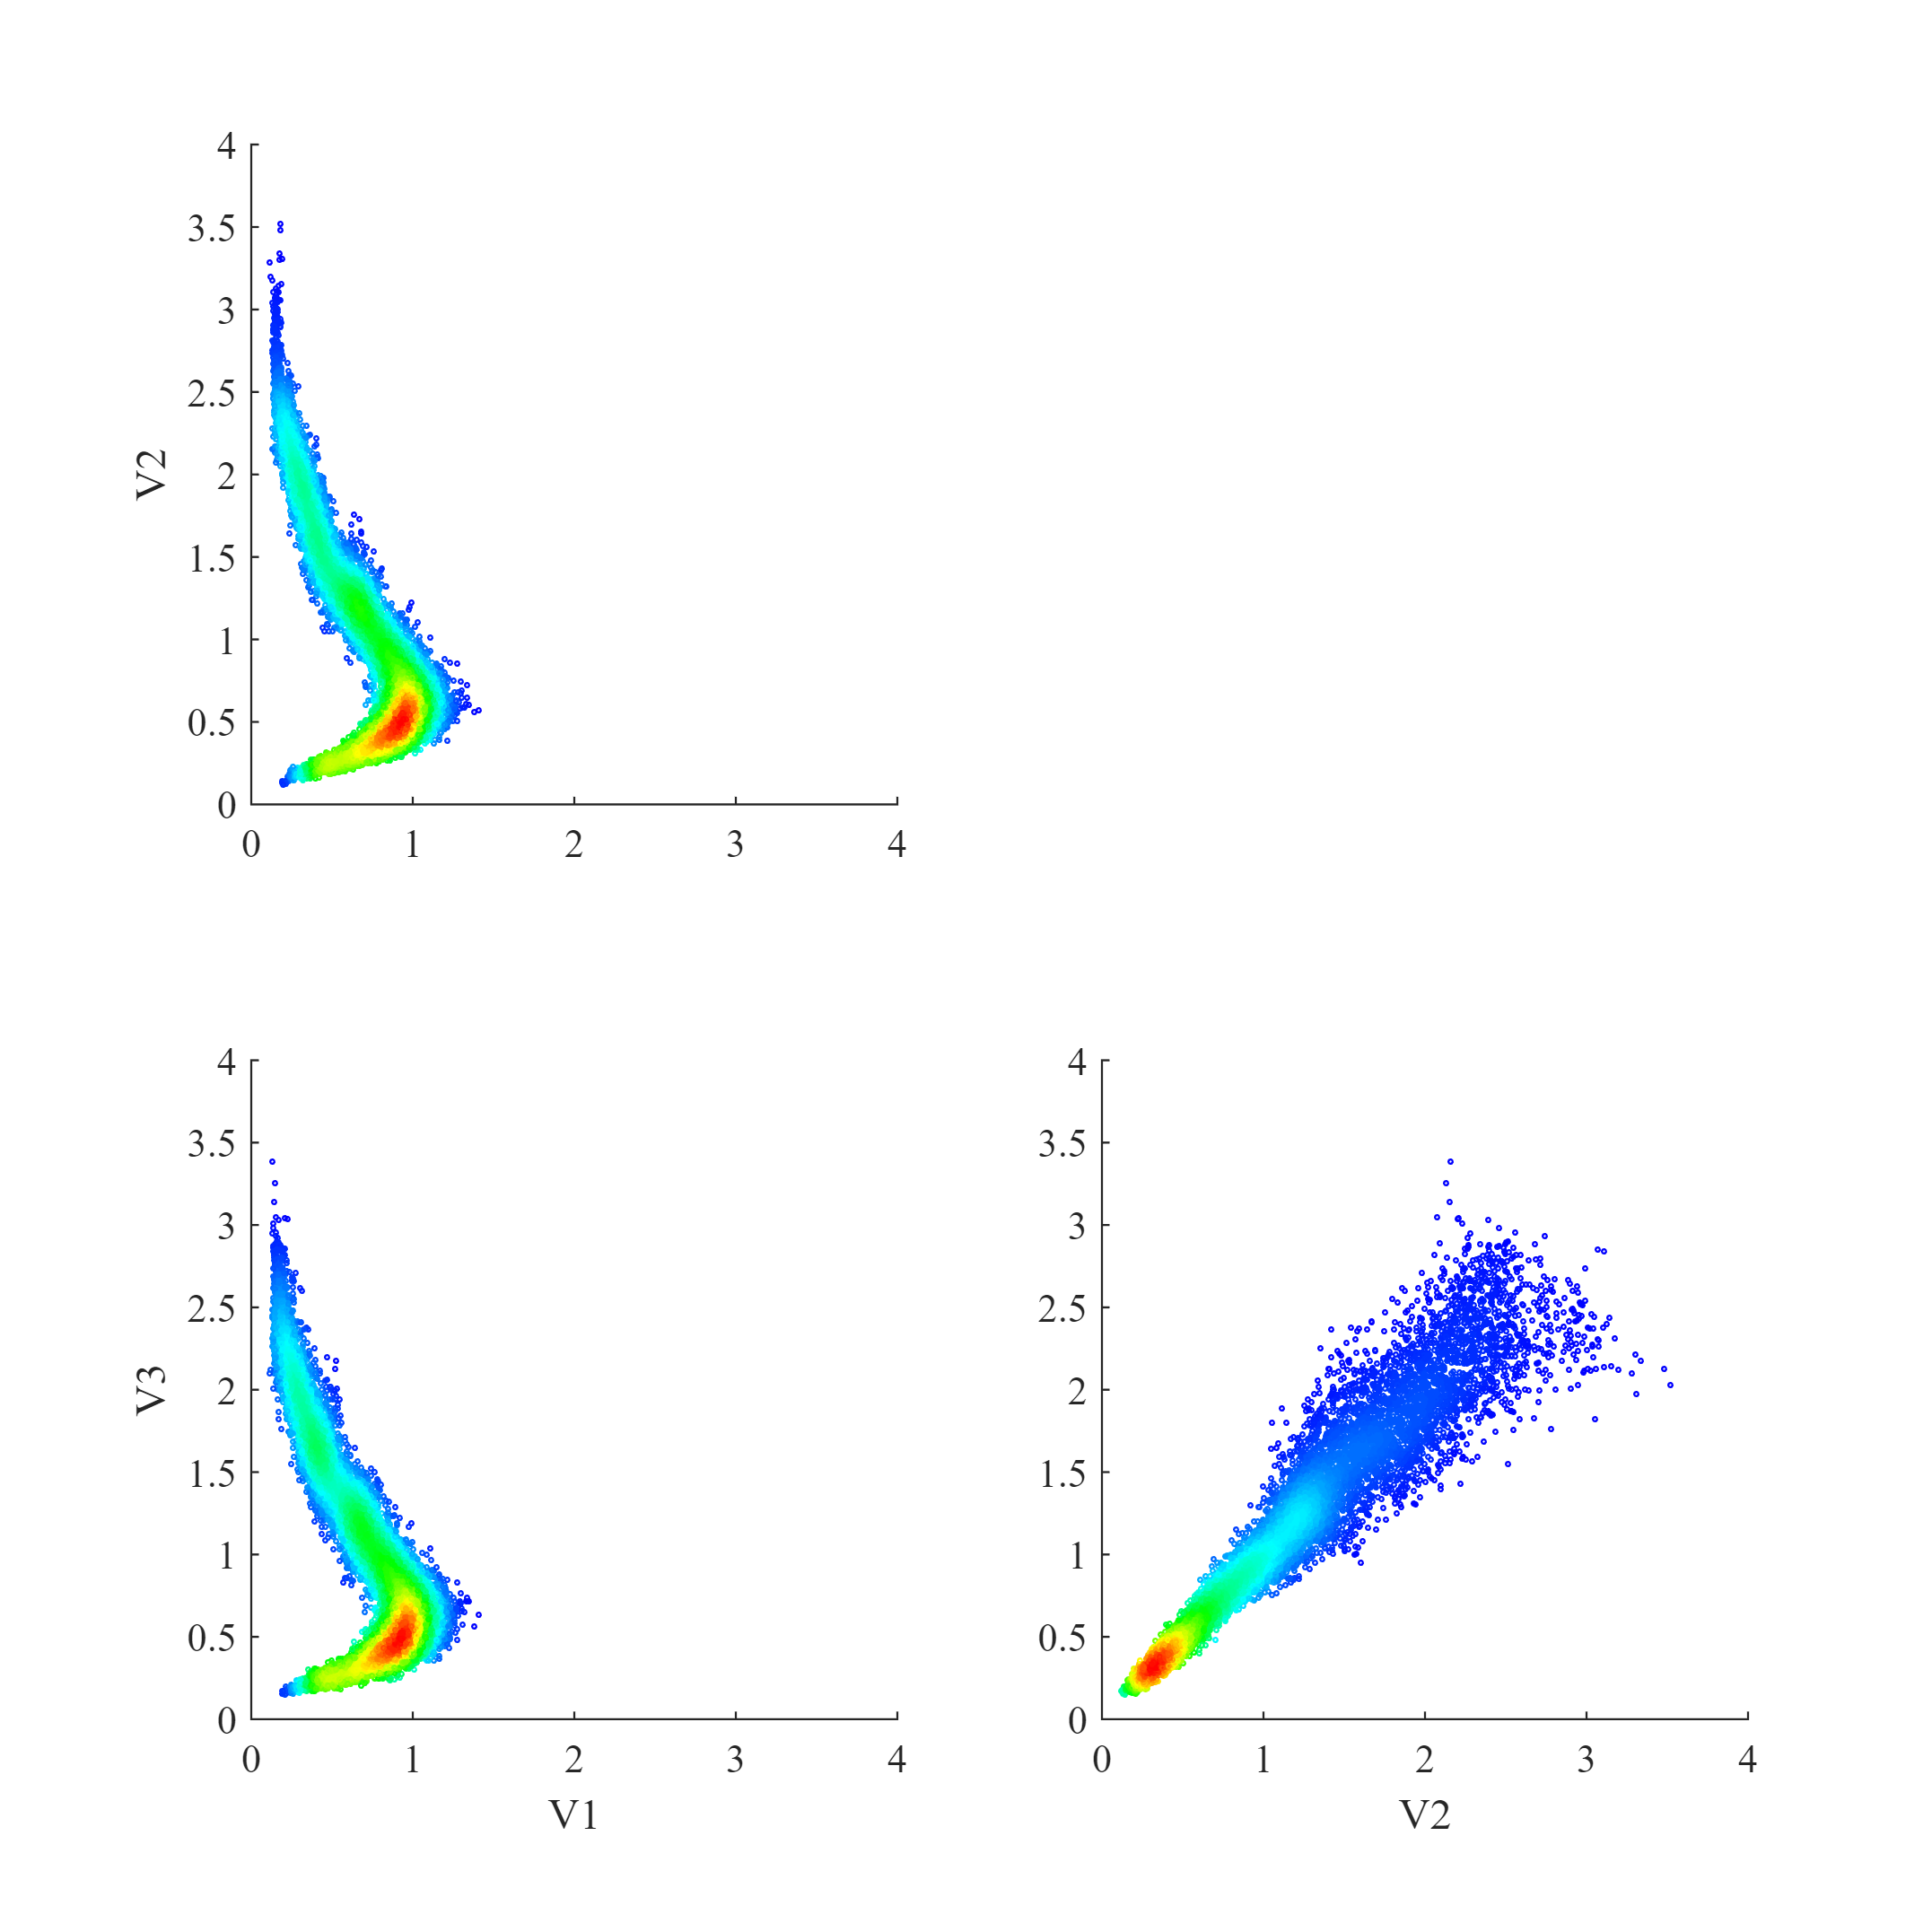

VariableNames(1:6) = {'x_axis','y_axis','z_axis','V1','V2','V3'};

spi=0;
spj=0;
figure( 'Position', [0 0 1200 1200]);
cs=hsv;
cs=(cs(1:172,:));
% cs=hsv;
% cs=(cs(1:172,:))
for i=2:3
for j=1:i-1
spj=spj+1;
subplot(2,2,(spj)+(spi)*2)
scatter(db(:,3+j),db(:,3+i),1,mvksdensity([db(:,3+j) db(:,3+i)],[db(:,3+j) db(:,3+i)]))
colormap(flipud(cs))
xlim([0 4])
ylim([0 4])
set(gca,'fontname','times')
% colormap(flipud(cs))
% caxis([-1 1])
if spj==1
    ylabel(VariableNames(i+3),'FontName','Times New Roman');
end
if spi==1
    xlabel(VariableNames(j+3),'FontName','Times New Roman');
end

end
spj=0;
spi=spi+1;
end

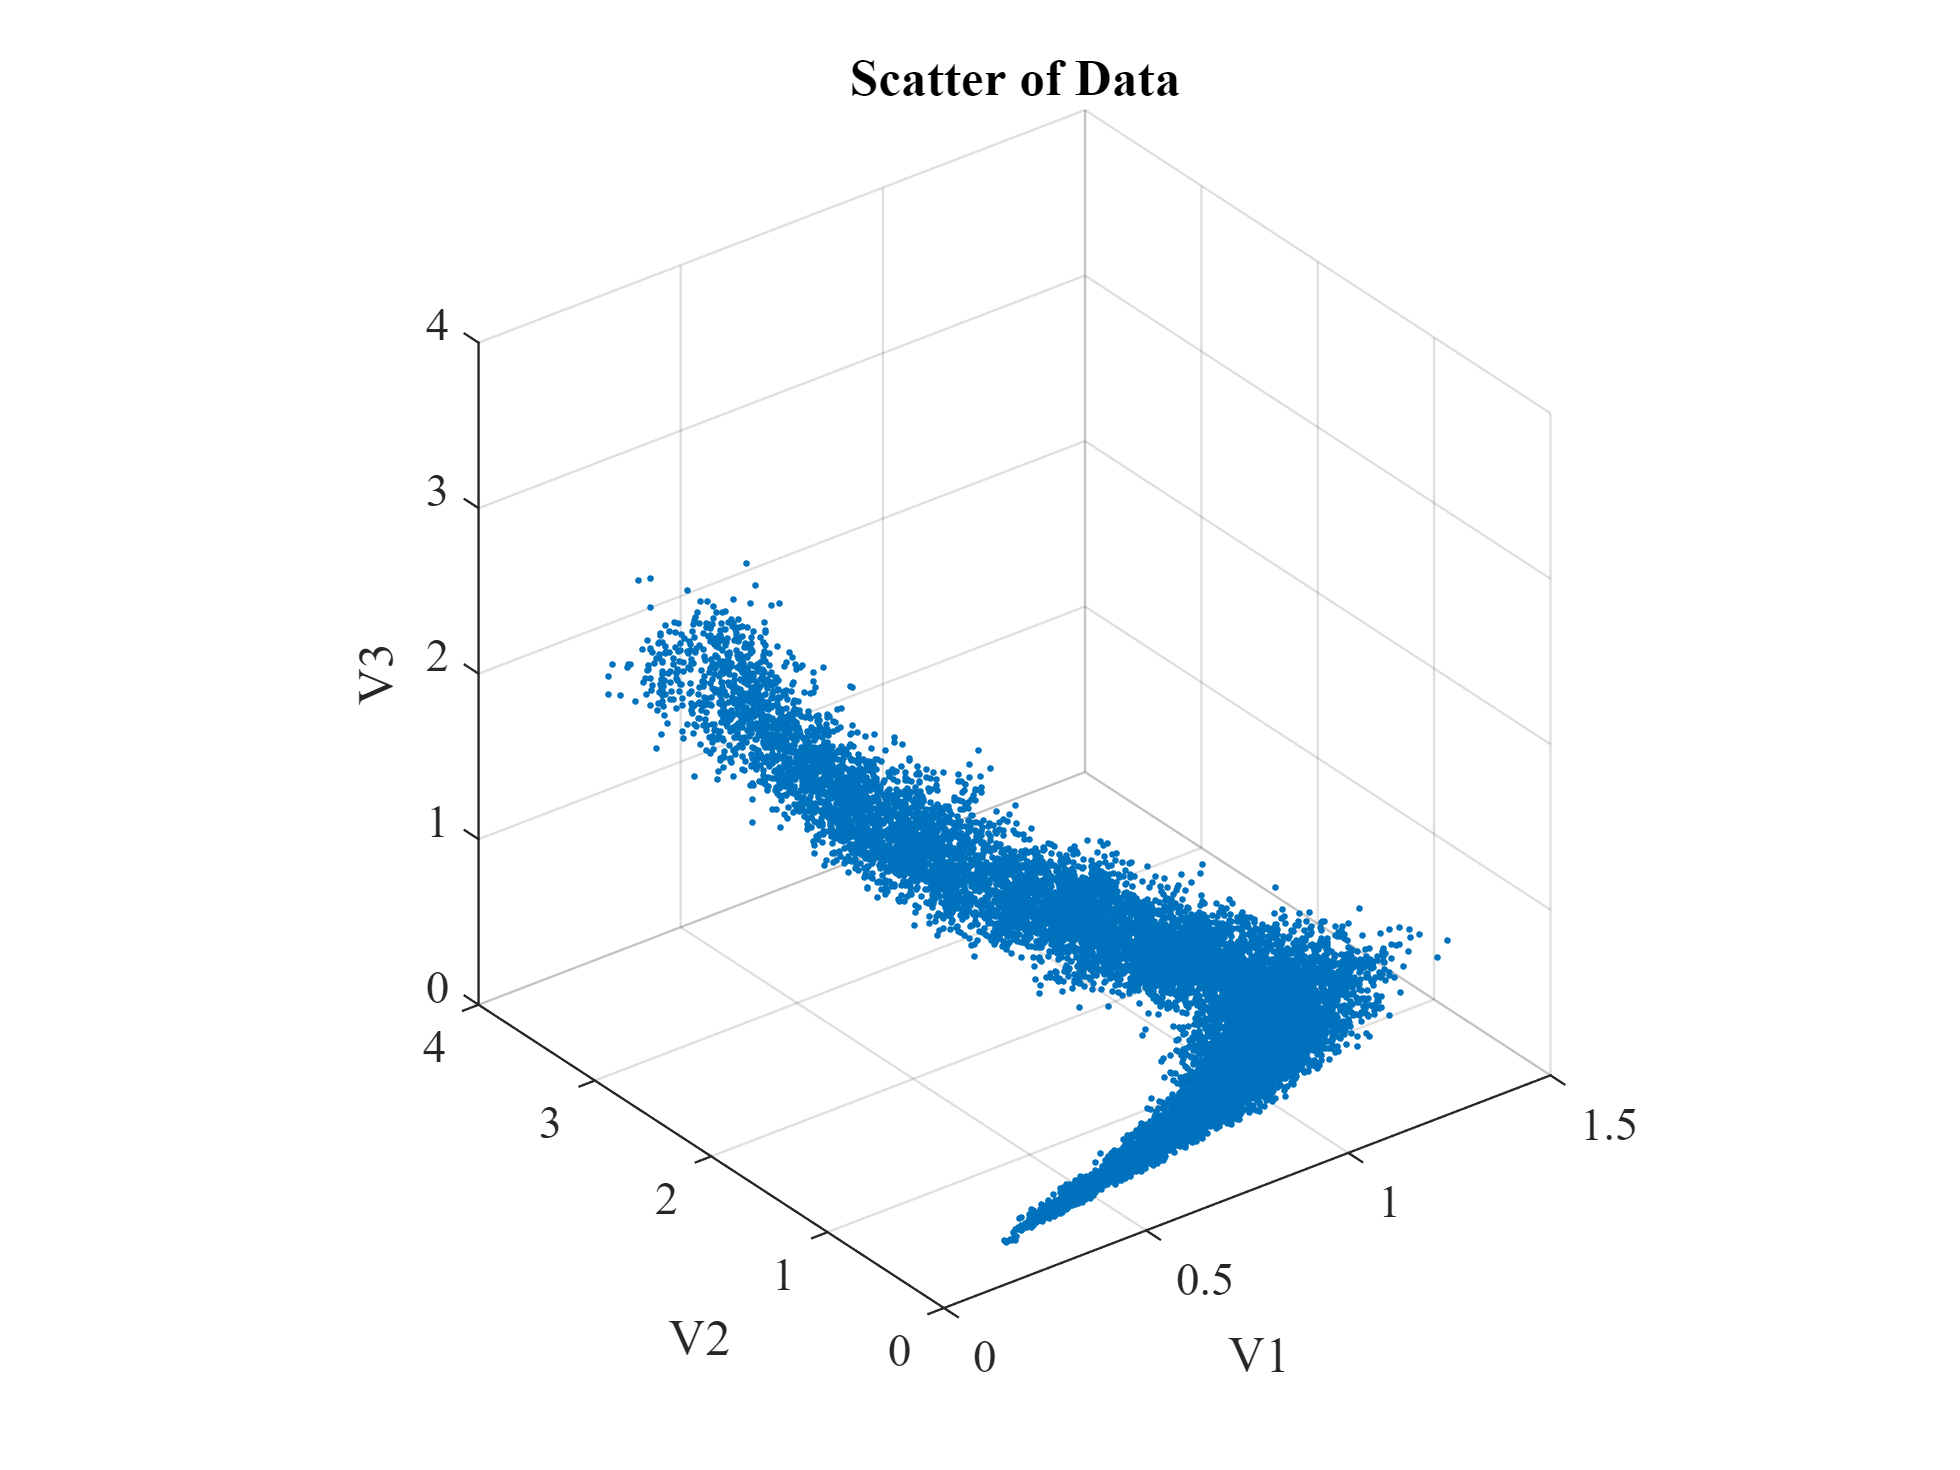

figure
scatter3(db(:,4),db(:,5),db(:,6),2,'fill')
pbaspect([1 1 1])

%view(0,90);
title('Scatter of Data')
xlabel('V1')
ylabel('V2')
zlabel('V3')

set(gca,'fontname','times')

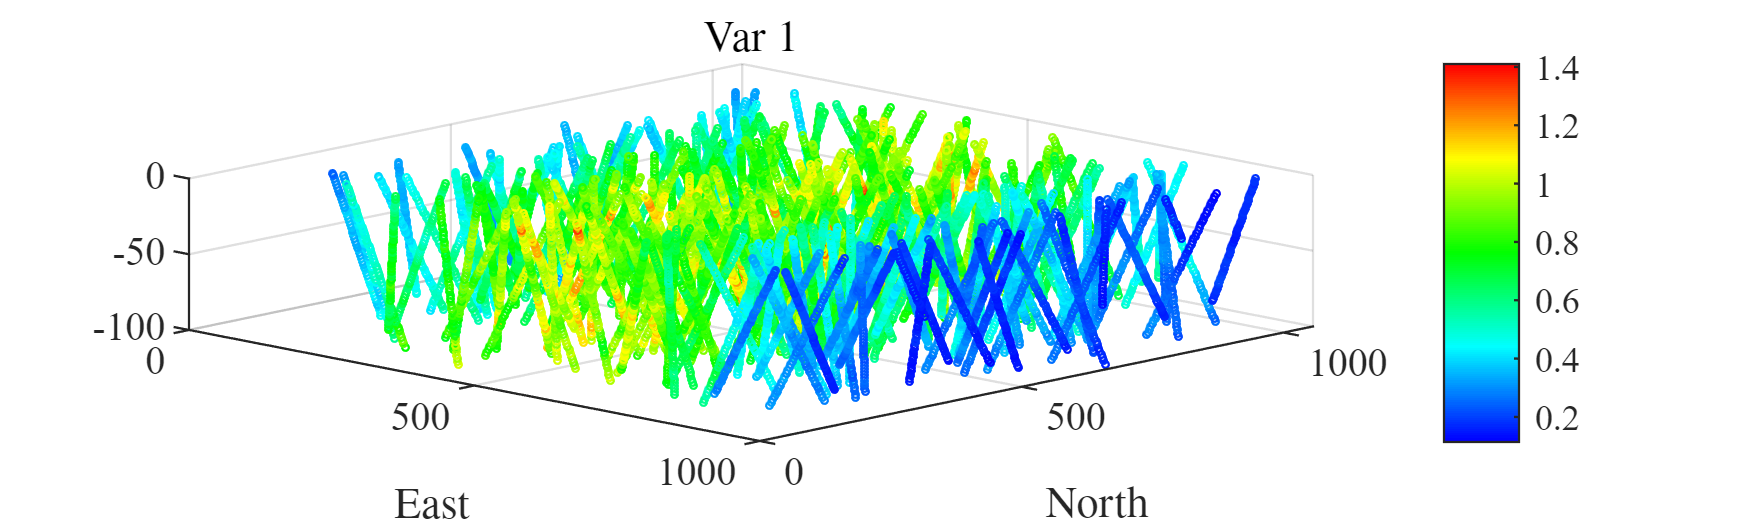

%locmap Var_2
figure( 'Position', [30 30 500 150]);
cs=hsv;
cs=(cs(1:172,:));
scatter3(db(:,1),db(:,2),db(:,3),2,db(:,4))
xlabel('East','interpreter','latex')
ylabel('North','interpreter','latex')
title('Var 1','interpreter','latex')
set(gca,'fontname','times')
colorbar
colormap(flipud(cs))
view([44.1 46.5])

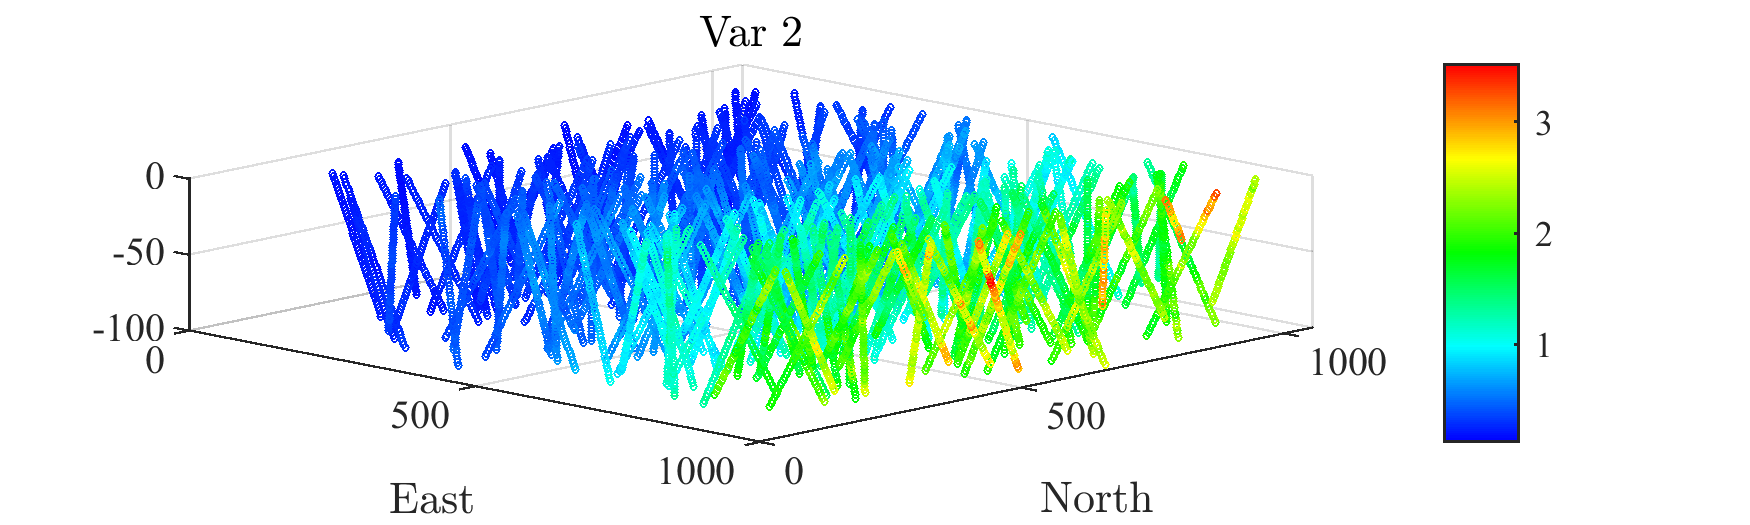

%locmap Var_2
figure( 'Position', [30 30 500 150]);
cs=hsv;
cs=(cs(1:172,:));
scatter3(db(:,1),db(:,2),db(:,3),2,db(:,5))
xlabel('East','interpreter','latex')
ylabel('North','interpreter','latex')
title('Var 2','interpreter','latex')
set(gca,'fontname','times')
colorbar
colormap(flipud(cs))
view([44.1 46.5])

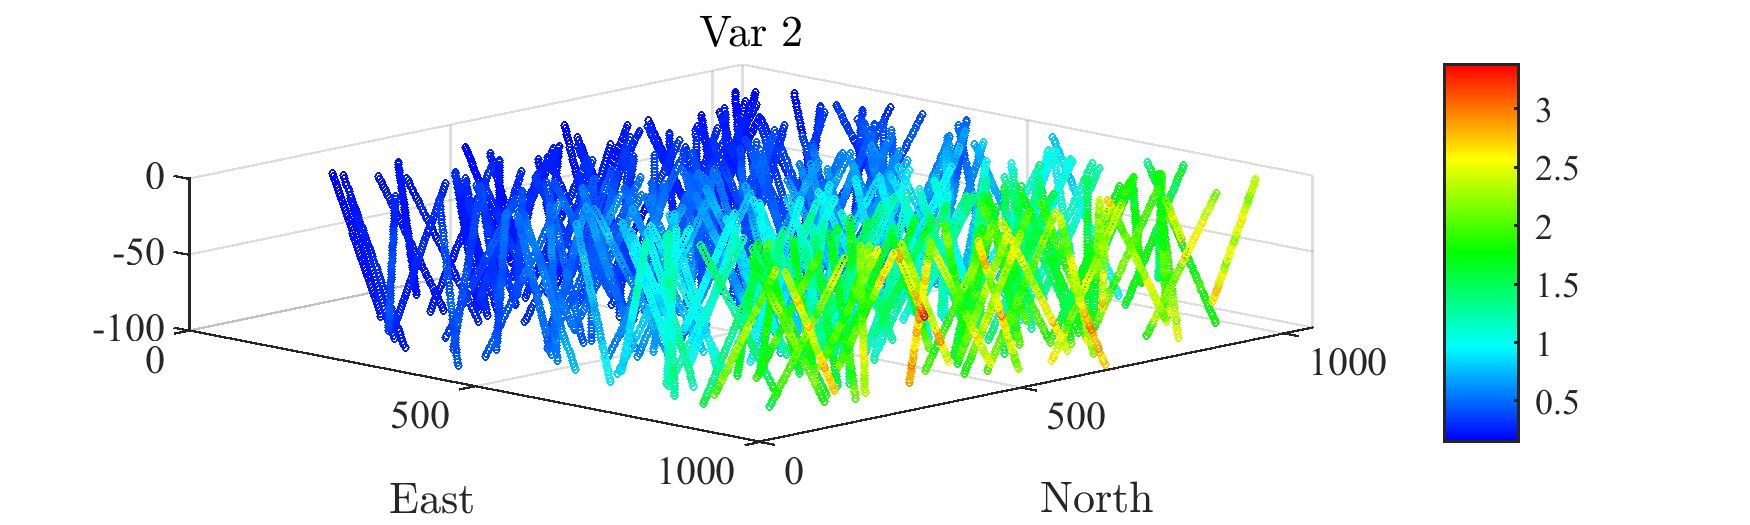

%locmap Var_3
figure( 'Position', [30 30 500 150]);
cs=hsv;
cs=(cs(1:172,:));
scatter3(db(:,1),db(:,2),db(:,3),2,db(:,6))
xlabel('East','interpreter','latex')
ylabel('North','interpreter','latex')
title('Var 2','interpreter','latex')
set(gca,'fontname','times')
colorbar
colormap(flipud(cs))
view([44.1 46.5])

## Inference of local correlation

[COV,g_db] = Local_corr(db(:,1:3),db(:,4:6),100); % inputs are coordinates, variables, and max. distance of search

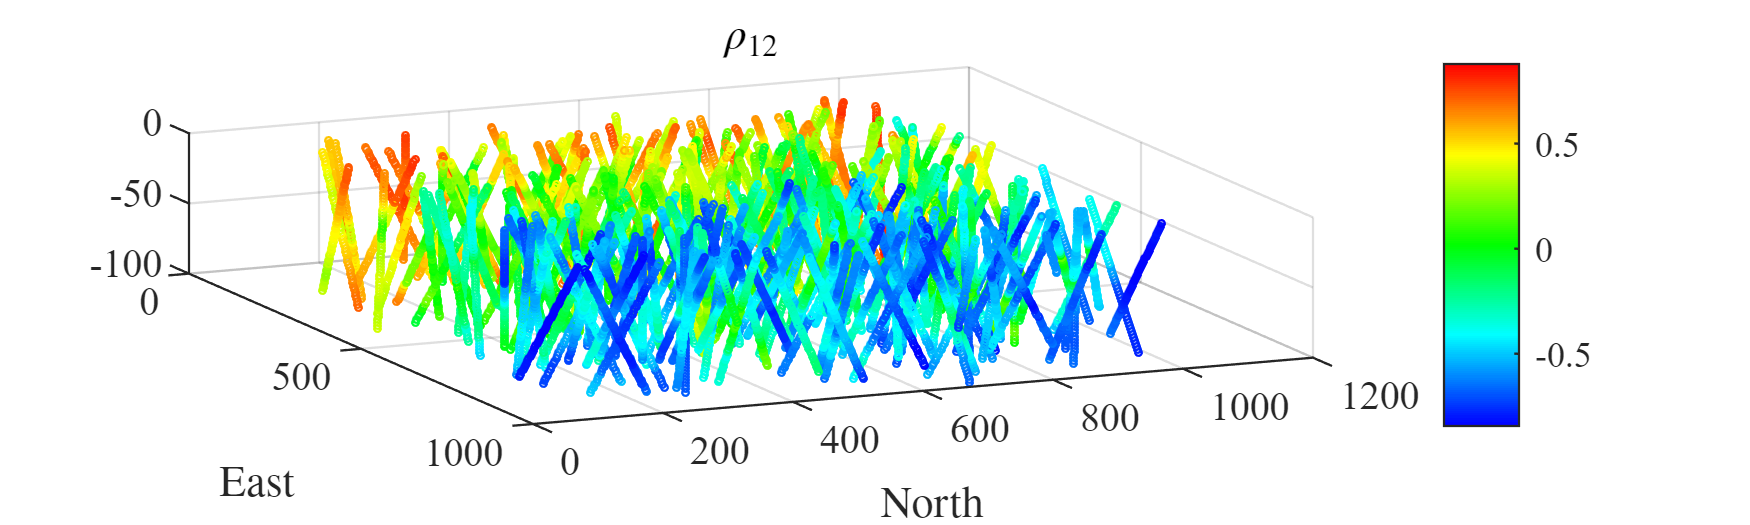

%locmap COV(1,2)
figure( 'Position', [30 30 500 150]);
cs=hsv;
cs=(cs(1:172,:));
scatter3(db(:,1),db(:,2),db(:,3),2,squeeze(COV(1,2,:)))
xlabel('East','interpreter','latex')
ylabel('North','interpreter','latex')
title('$\rho_{12}$','interpreter','latex')
set(gca,'fontname','times')
colorbar
colormap(flipud(cs))
view([66.2 49.5])

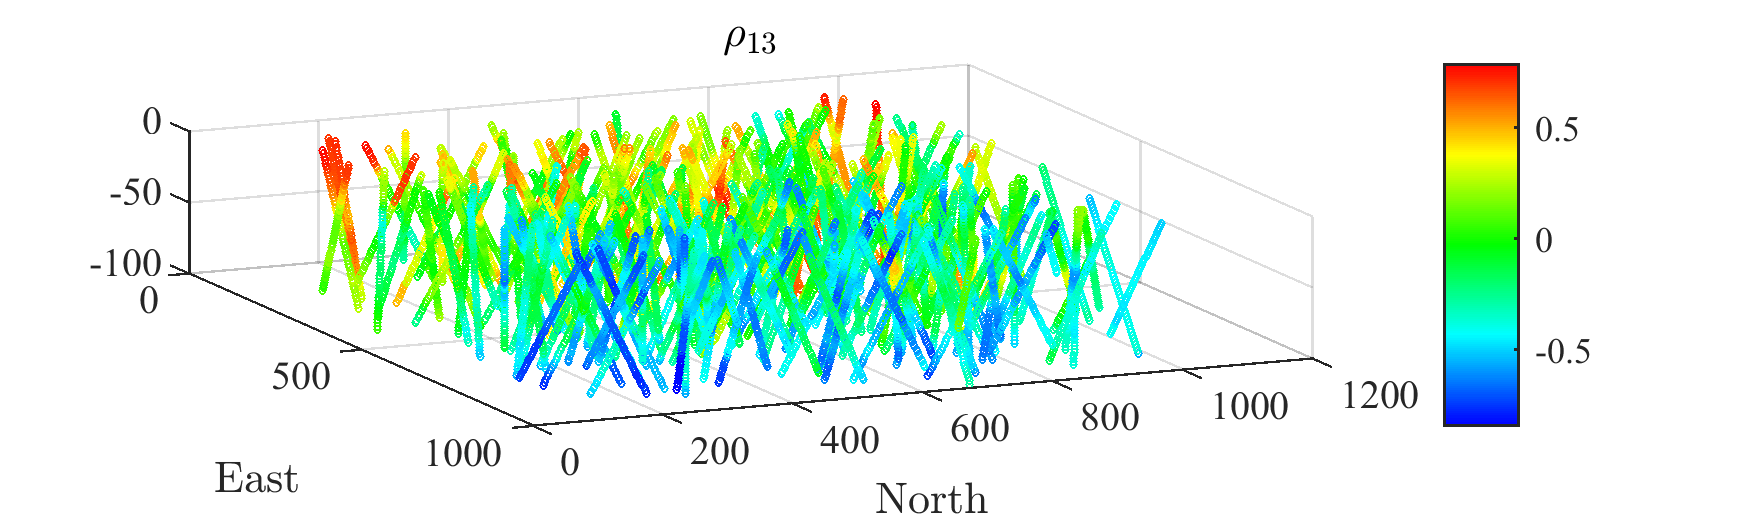

%locmap COV(1,3)
figure( 'Position', [30 30 500 150]);
cs=hsv;
cs=(cs(1:172,:));
scatter3(db(:,1),db(:,2),db(:,3),2,squeeze(COV(1,3,:)))
xlabel('East','interpreter','latex')
ylabel('North','interpreter','latex')
title('$\rho_{13}$','interpreter','latex')
set(gca,'fontname','times')
colorbar
colormap(flipud(cs))
view([66.2 49.5])

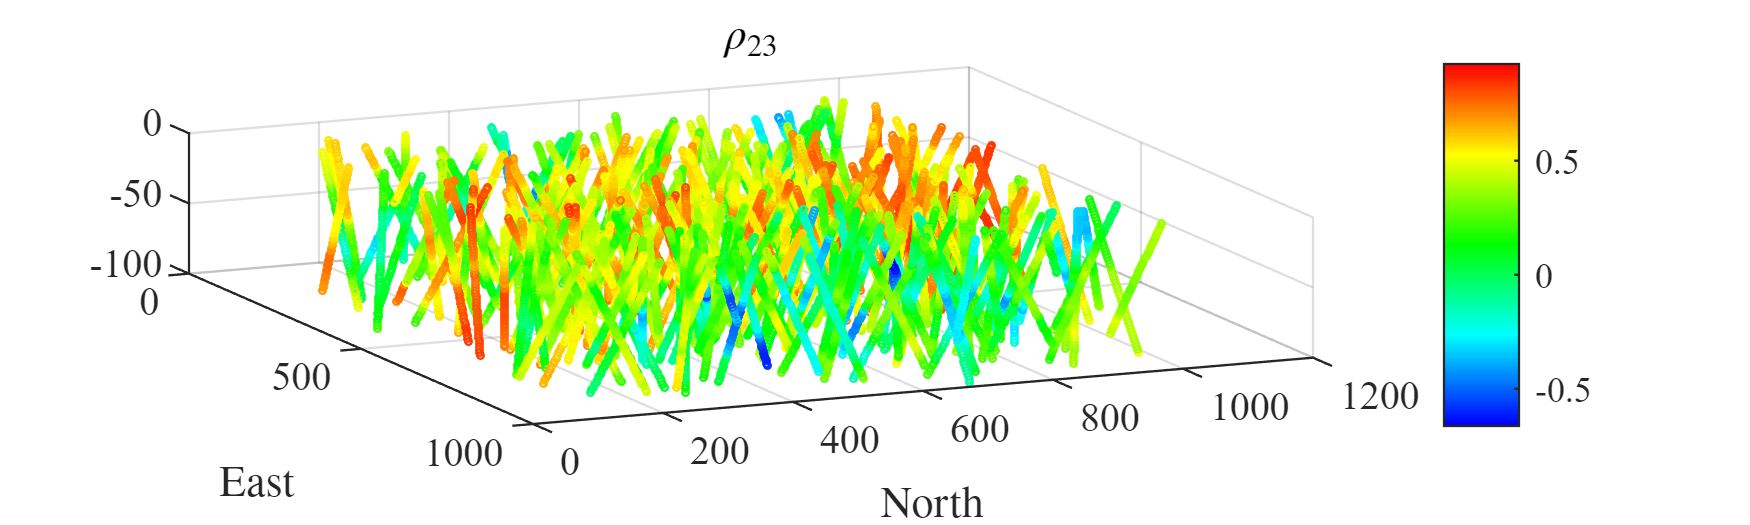

%locmap COV(2,2)
figure( 'Position', [30 30 500 150]);
cs=hsv;
cs=(cs(1:172,:));
scatter3(db(:,1),db(:,2),db(:,3),2,squeeze(COV(2,3,:)))
xlabel('East','interpreter','latex')
ylabel('North','interpreter','latex')
title('$\rho_{23}$','interpreter','latex')
set(gca,'fontname','times')
colorbar
colormap(flipud(cs))
view([66.2 49.5])

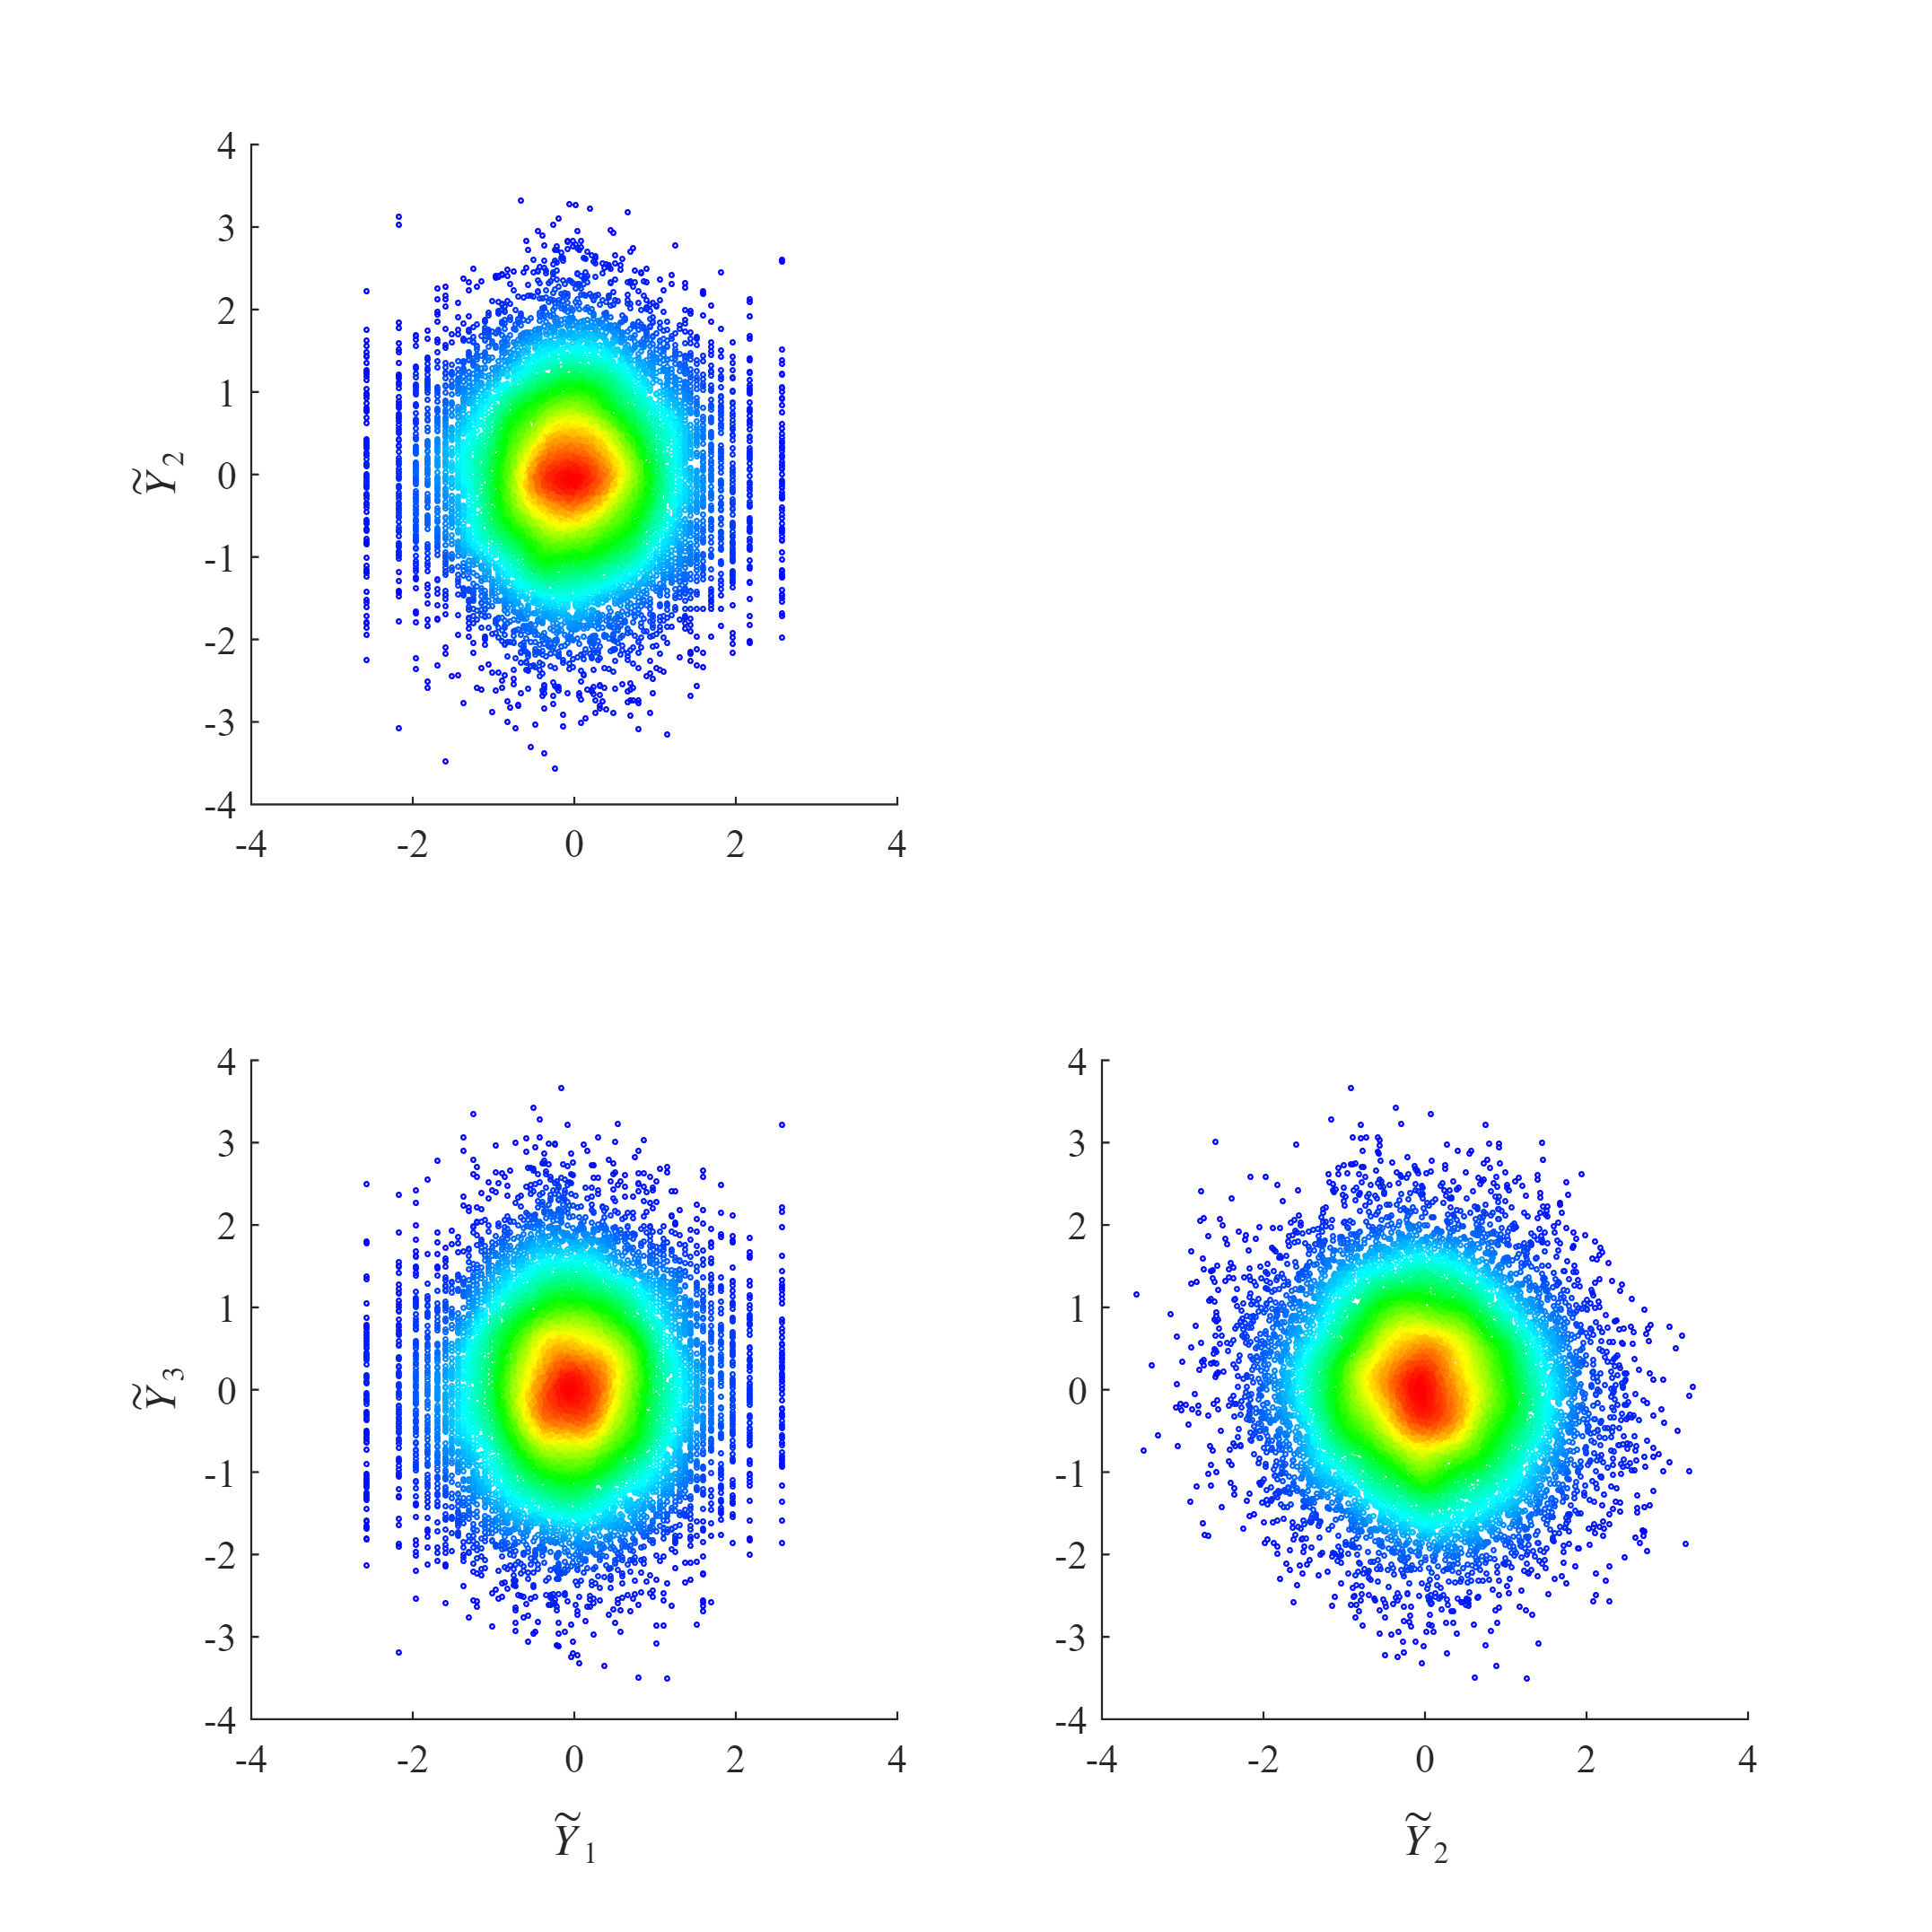

%Scatterplot of local NS transformation

VariableNames(1:3) = {'$\tilde{Y}_1$','$\tilde{Y}_2$','$\tilde{Y}_3$'};

spi=0;
spj=0;
figure( 'Position', [0 0 1200 1200]);
cs=hsv;
cs=(cs(1:172,:));

for i=2:3
for j=1:i-1
spj=spj+1;
subplot(2,2,(spj)+(spi)*2)
scatter(g_db(:,j),g_db(:,i),1,mvksdensity([g_db(:,j) g_db(:,i)],[g_db(:,j) g_db(:,i)]))
colormap(flipud(cs))
xlim([-4 4])
ylim([-4 4])
set(gca,'fontname','times')

if spj==1
    ylabel(VariableNames(i),'FontName','Times New Roman','interpreter','latex');
end
if spi==1
    xlabel(VariableNames(j),'FontName','Times New Roman','interpreter','latex');
end

end
spj=0;
spi=spi+1;
end

## Run Euclidean Kmeans

N_k=3; %% Set the number of means
seed=rand*9784498+11;
rand('state',seed);
index3=(tril(ones(3),-1))>0;
index3=index3(:);
indexsel3=(1:9);
indexsel3=indexsel3(index3);

Ssq_full = squeeze(reshape(COV,1,9,size(db,1)))';
Ssq_full_lim= Ssq_full(:,indexsel3);

opts = statset('Display','final');
[idx,C] = kmeans(Ssq_full_lim,N_k,'Distance','cityblock',...
    'Replicates',5,'Options',opts);

Replicate 1, 19 iterations, total sum of distances = 7571.32.
Replicate 2, 34 iterations, total sum of distances = 7571.35.
Replicate 3, 21 iterations, total sum of distances = 7571.32.
Replicate 4, 27 iterations, total sum of distances = 7571.32.
Replicate 5, 33 iterations, total sum of distances = 7571.35.
Best total sum of distances = 7571.32


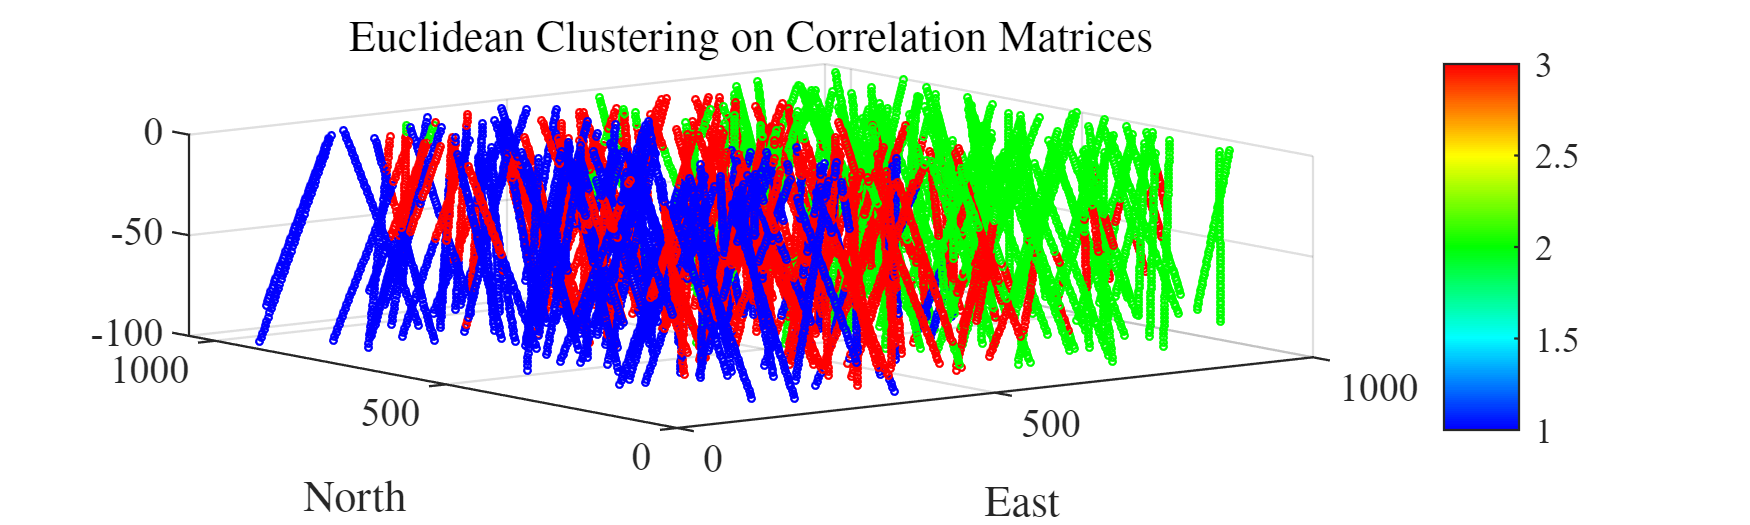

%locmap COV(2,2)
figure( 'Position', [30 30 500 150]);
cs=hsv;
cs=(cs(1:172,:));
scatter3(db(:,1),db(:,2),db(:,3),2,idx)
xlabel('East','interpreter','latex')
ylabel('North','interpreter','latex')
title('Euclidean Clustering on Correlation Matrices','interpreter','latex')
set(gca,'fontname','times')
colorbar
colormap(flipud(cs))

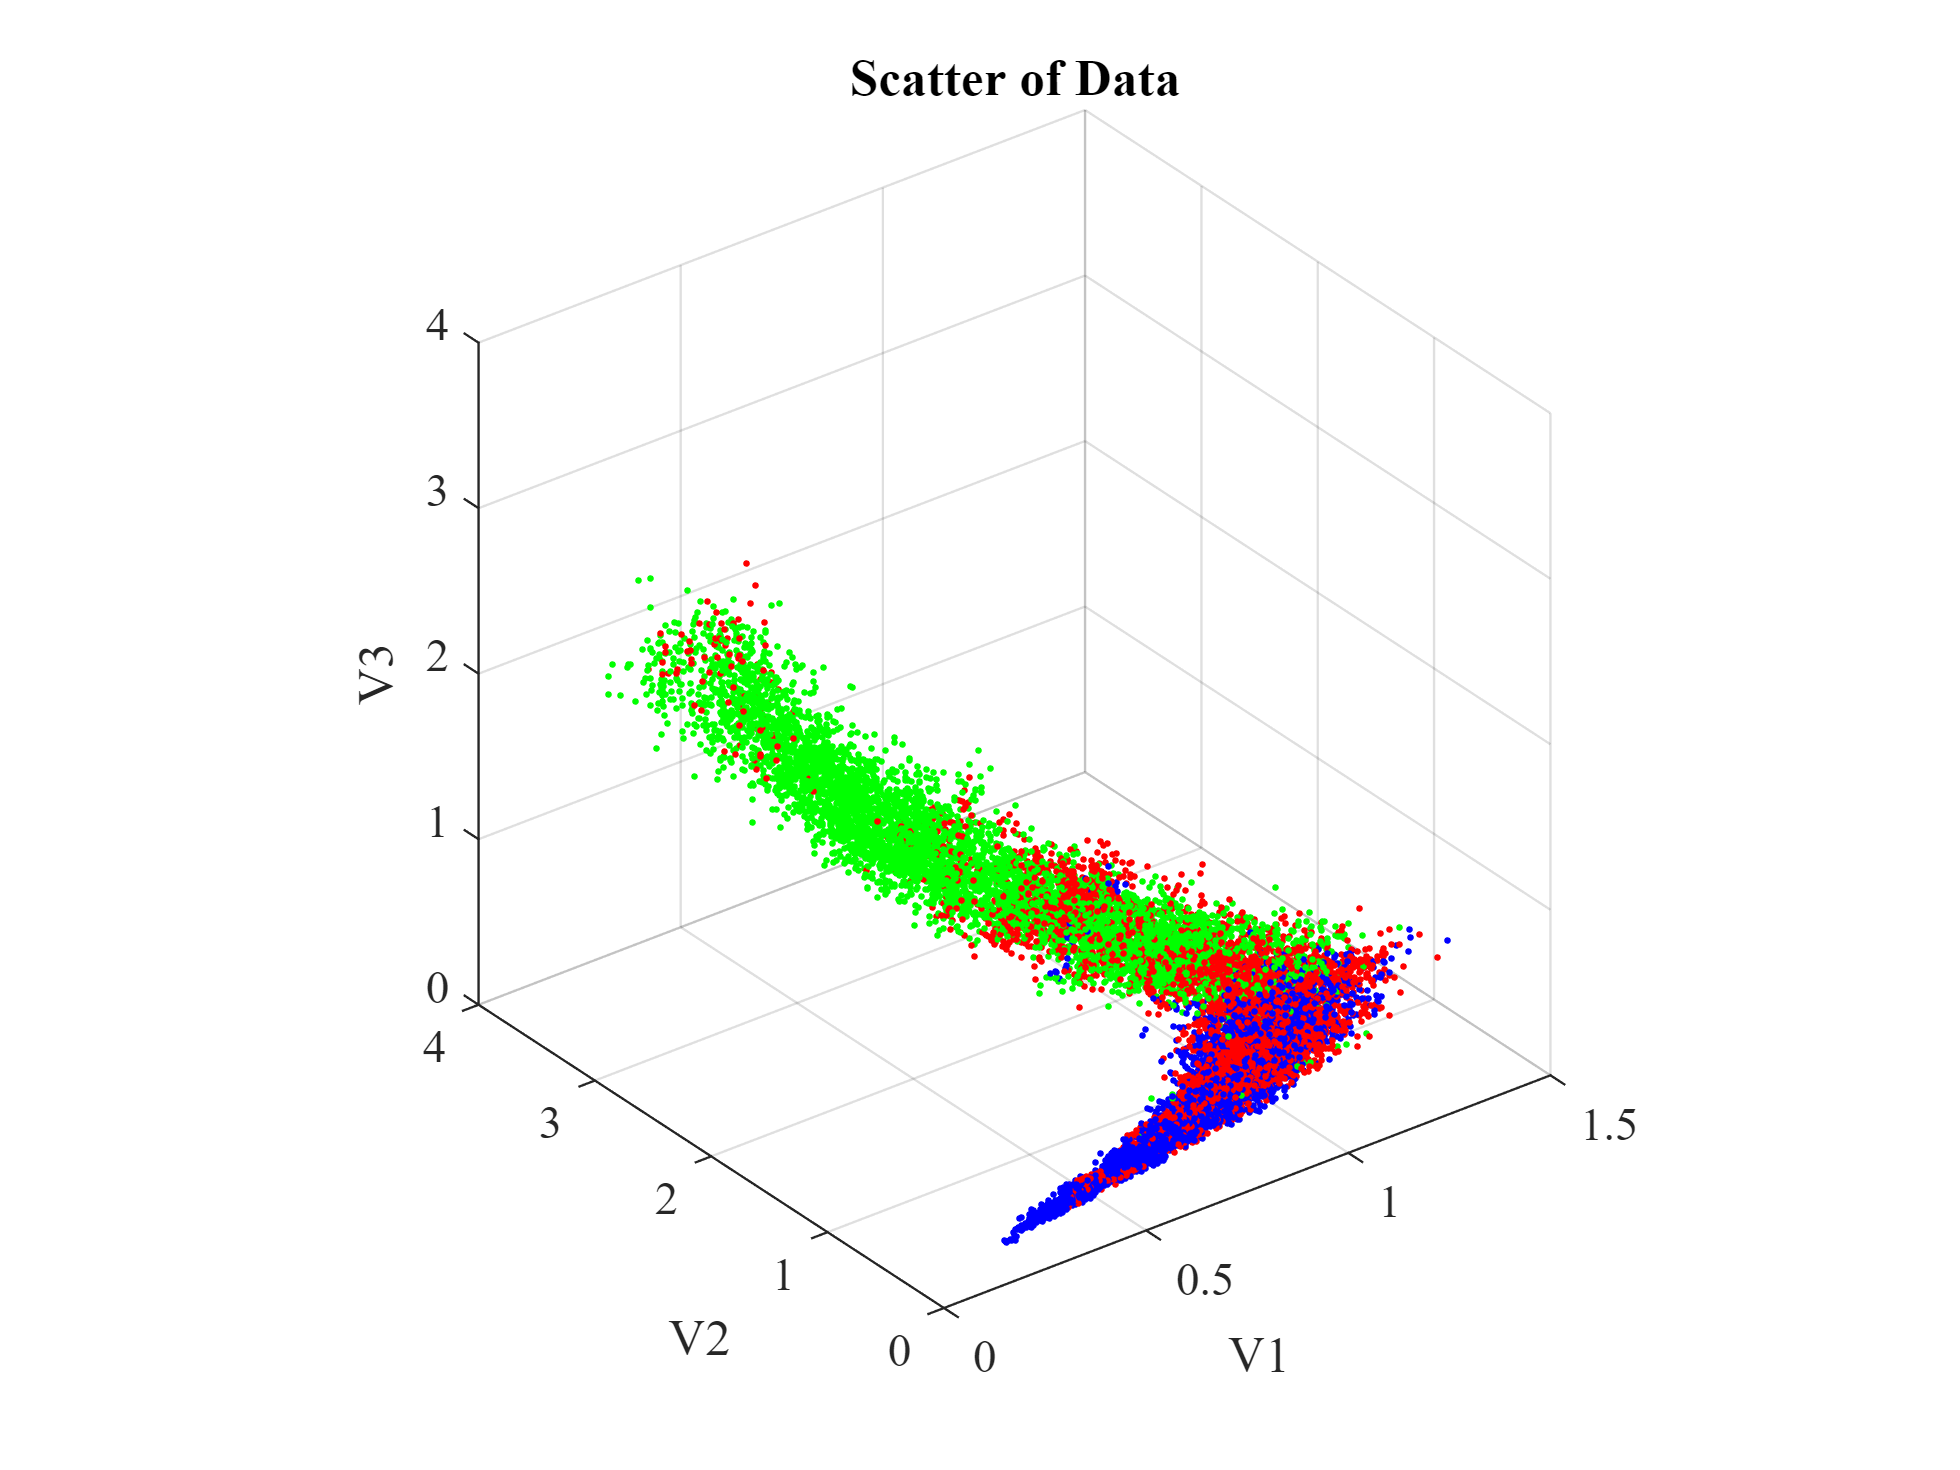

figure
cs=hsv;
cs=(cs(1:172,:));
colormap(flipud(cs))
scatter3(db(:,4),db(:,5),db(:,6),2,idx,'fill')
pbaspect([1 1 1])

%view(0,90);
title('Scatter of Data')
xlabel('V1')
ylabel('V2')
zlabel('V3')

set(gca,'fontname','times')

### 2.1- Run Riemannian K-means on data

matrixSize = 3;
COVmm=COV;
k_COV=[];

%initializing K (correlation) centers

yyyy = floor(linspace(1,size(db,1),N_k+1));

for n = 1:N_k
k_COV(:,:,n,1)=mean(COVmm(:,:,yyyy(n):yyyy(n+1)),3);
end

pause(1)
'RUNNING CLUSTERING'

ans = 'RUNNING CLUSTERING'

% RUN CLUSTERING

N_itermax = 200;
N_itermax_D = 200;
tol = 10^-5;

niter = 0;
fc = 0;

niterD = 0;
del=0.05;

%
flag_im=0;
flag_cond=0;
N_itermax_K=5;
niter_k=0;
TAG=zeros(size(COVmm,3),N_itermax_K);
Ct_tt=zeros(matrixSize,matrixSize,size(COVmm,3),N_k);

% step 1 : embedd each Corr Matrix into the SPD space, with respect to each K center
while (niter_k<N_itermax_K)
   niter_k = niter_k+1
%initialization
    for nk = 1:N_k
        nk;
        A=k_COV(:,:,nk,niter_k);
        A=(A+A')/2;
        NTrial = size(COVmm,3);
        N_elec = size(COVmm,1);

        Tri = zeros(N_elec,N_elec,NTrial);
        for n = 1:NTrial
            n;
            niterD = 0;
            D_t=eye(N_elec);
            while (niterD<N_itermax_D)
                niterD = niterD+1;
                A_inv=A^-1;
                A_inv=(A_inv+A_inv')/2;
                dum=D_t*logm(COVmm(:,:,n)*D_t*A_inv*D_t);
                dum=(dum+dum')/2;
                cond=COVmm(:,:,n)*D_t*A_inv*D_t-eye(N_elec);
                if sqrt(trace(cond'*cond))>1
                    dum=dum.*0;
                end

                Tri=eye(N_elec).*(dum+dum');
                D_t=D_t*expm(-del*D_t^-1*Tri);
                D_t=(D_t+D_t')/2;
            end
            Ct_tt(:,:,n,nk)=((D_t*COVmm(:,:,n)*D_t)+(D_t*COVmm(:,:,n)*D_t)')/2;
        end
    end

% step 2 : Tagging, i.e, find the closest mean for each sample and tag

    
    for n = 1:NTrial
        dum_dist=Inf;
    for nk = 1:N_k
        dist=distance_riemann(Ct_tt(:,:,n,nk),k_COV(:,:,nk,niter_k));
        if imag(dist)>0
            dist=Inf;
            flag_im=1;
        end
        if dist<dum_dist
            dum_dist=dist;
            TAG(n,niter_k)=nk;
        end    
    end
    end

% step 3 : re comptue K means once each new tagged set

    L=[];
    for nk = 1:N_k
        nk;
        index=TAG(:,niter_k)==nk;
        COV_nk=COVmm(:,:,index);
        NTrial = size(COV_nk,3);
        N_elec = size(COV_nk,1);
        niter=0;
        A=k_COV(:,:,nk,niter_k);
        Ct_t=zeros(matrixSize,matrixSize,NTrial);
        while (niter<N_itermax)
            niter = niter+1;

            Tri = zeros(N_elec,N_elec,NTrial);
            
            for n = 1:NTrial
                D_t=eye(N_elec);
                niterD = 0;
                while (niterD<N_itermax_D)
                    niterD = niterD+1;
                    dum=D_t*logm(COV_nk(:,:,n)*D_t*A^-1*D_t);
                    cond=COV_nk(:,:,n)*D_t*A^-1*D_t-eye(N_elec);
                    if sqrt(trace(cond'*cond))>1
                        dum=dum.*0;
                        flag_cond=1;
                    end

                    Tri=eye(N_elec).*(dum+dum');
                    D_t=D_t*expm(-del*D_t^-1*Tri);
                end
                Ct_t(:,:,n)=D_t*COV_nk(:,:,n)*D_t;
            end

            % Tangent space mapping A=init B =Cov
            T = Tangent_space(Ct_t,A);
            % sum of the squared distance
            fcn = sum(sum(T.^2));
            % improvement
            conv = abs((fcn-fc)/fc);
            if conv<tol % break if the improvement is below the tolerance
               break; 
            end
            % arithmetic mean in tangent space
            TA = mean(T,2);
            % back to the manifold
            A = UnTangent_space(TA,A);
            % back to Corr(n)
            A = diag(diag(A))^-0.5*A*diag(diag(A))^-0.5;
            fc = fcn;
        end
        
        k_COV(:,:,nk,niter_k+1)=A;
        if niter==N_itermax
            disp('Warning : Maximun Number of Iterations Attended');
        end
    end

    % repeat
end

niter_k = 1

niter_k = 2

niter_k = 3

niter_k = 4

niter_k = 5

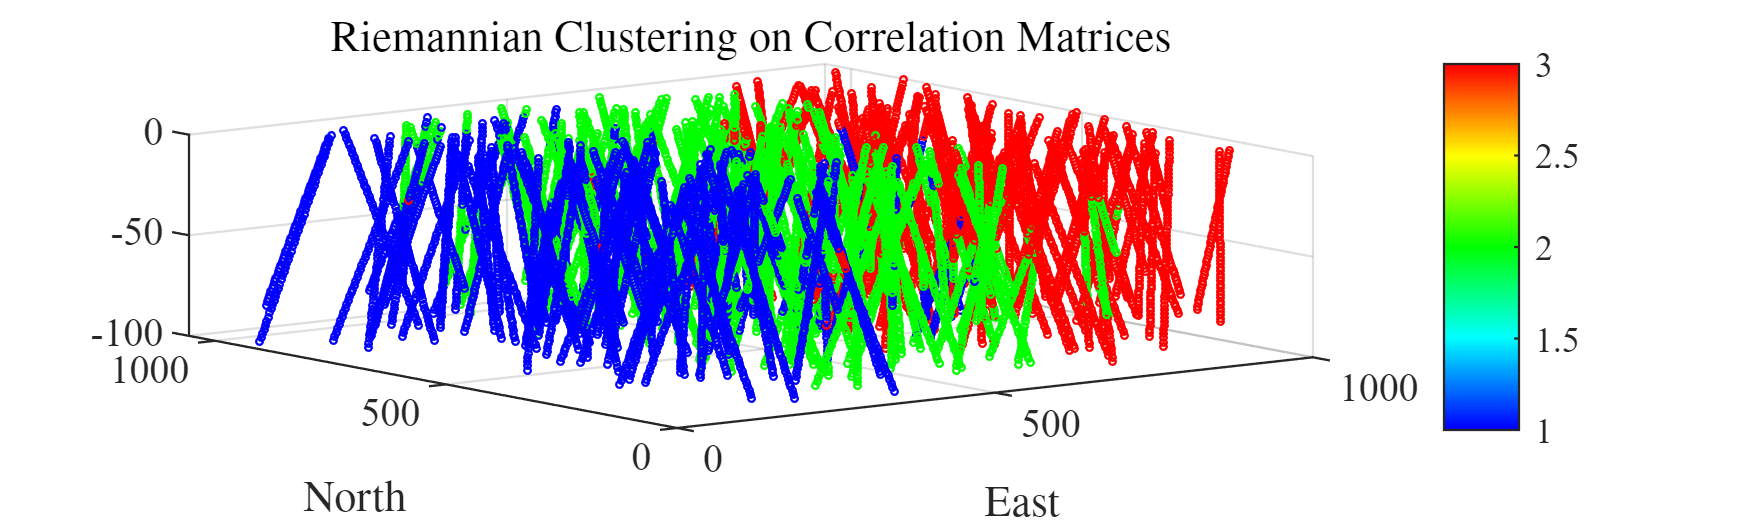

figure( 'Position', [30 30 500 150]);
cs=hsv;
cs=(cs(1:172,:));
scatter3(db(:,1),db(:,2),db(:,3),2,TAG(:,5))
xlabel('East','interpreter','latex')
ylabel('North','interpreter','latex')
title('Riemannian Clustering on Correlation Matrices','interpreter','latex')
set(gca,'fontname','times')
colorbar
colormap(flipud(cs))

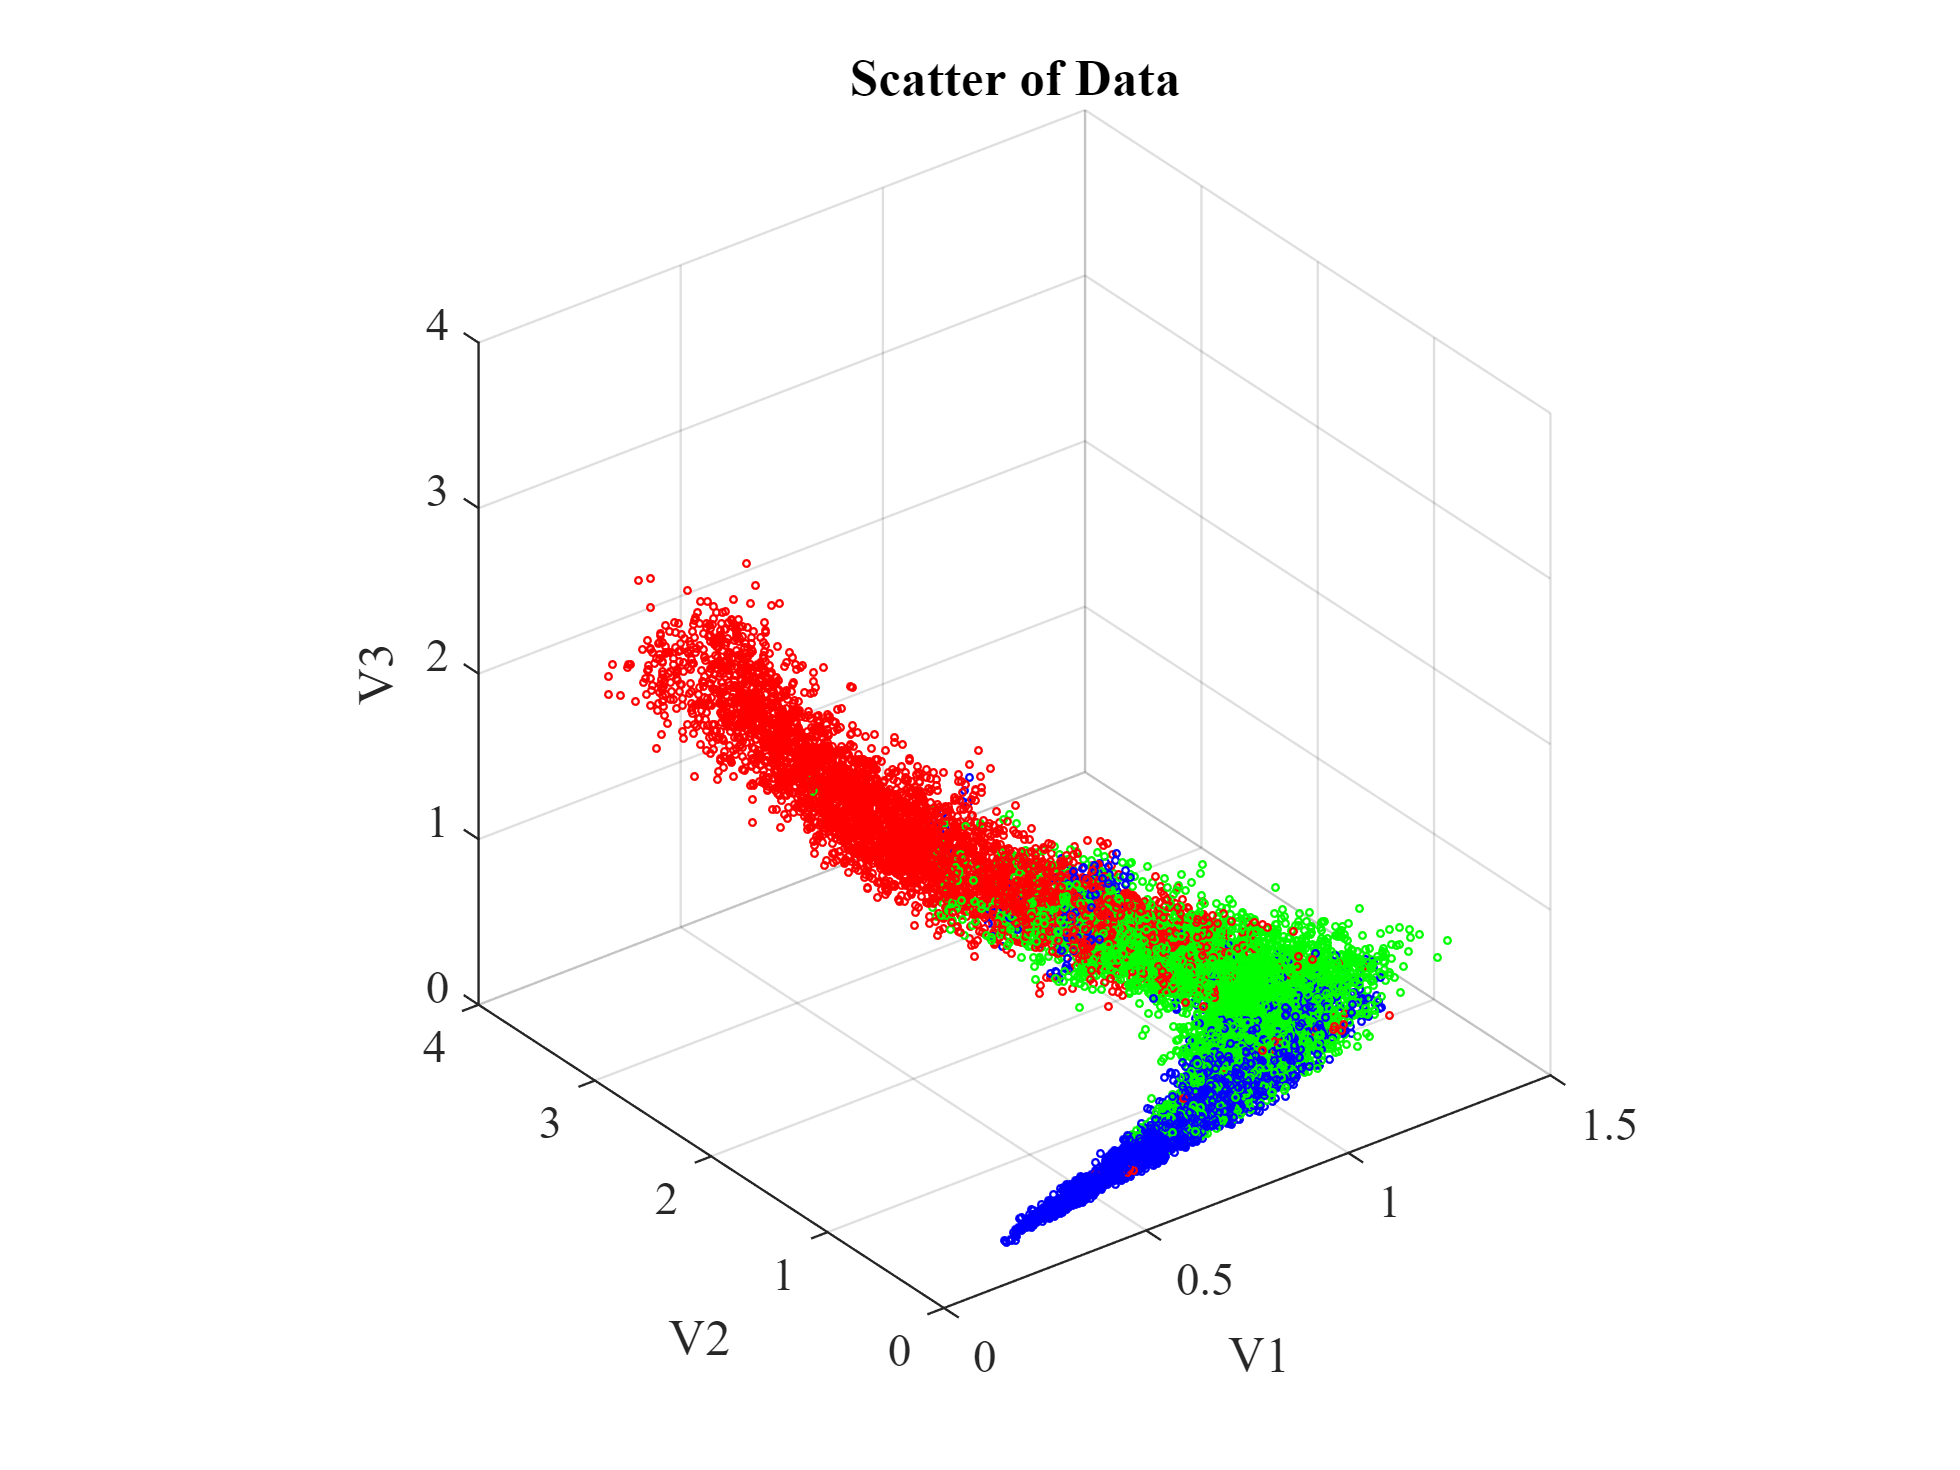

figure
cs=hsv;
cs=(cs(1:172,:));
colormap(flipud(cs))
scatter3(db(:,4),db(:,5),db(:,6),2,TAG(:,5))
pbaspect([1 1 1])

%view(0,90);
title('Scatter of Data')
xlabel('V1')
ylabel('V2')
zlabel('V3')

set(gca,'fontname','times')

### 2.5- Plotting progress of K-means on data, Prob plots

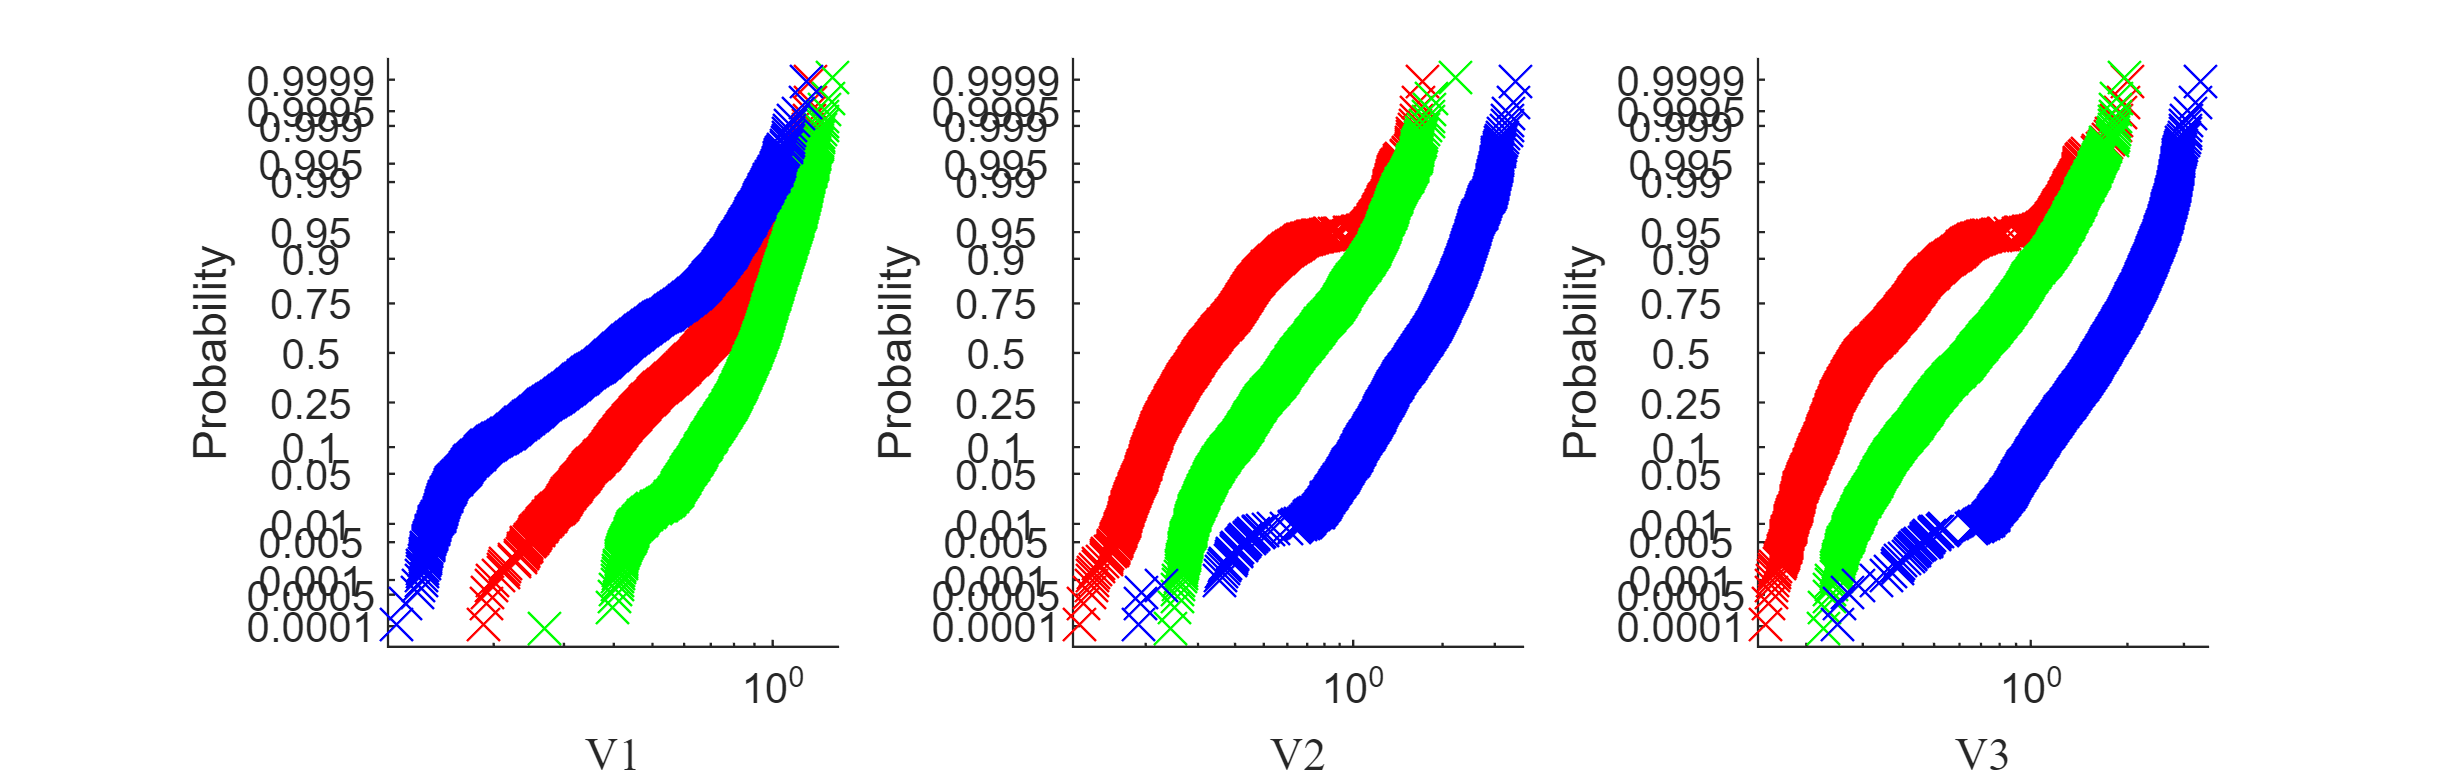

VariableNames(1:3) = {'V1','V2','V3'};

figure( 'Position', [0 0 5000 1600]);
cmap=colormap(hsv(N_k));
for variable_ev=1:3
    g_all=[];
    xall=[];
for km = 1:N_k
        index=find(TAG(:,4)==km);
        g1 = repmat({km},length(index),1);
        g_all=[g_all;g1];
        xall=[xall;db(index,3+variable_ev)];
        
    if km == 1
        subplot(1,3,variable_ev)
        h1(km) = probplot('lognormal',db(index,3+variable_ev),'noref');
        ha = get(h1(km),'Parent'); % get the handle to the created axis
        xlabel(VariableNames(variable_ev),'FontName','Times New Roman');
        title([]);
    else
        h1(km) = probplot(ha,'lognormal',db(index,3+variable_ev),'noref'); % reuse the same axis
        xlabel(VariableNames(variable_ev),'FontName','Times New Roman');
        title([]);
    end
    set(h1(km),'color',cmap(km,:),'markersize',10);
    hold on; 
end
end

## MATLAB Functions

function [COV,g_db] = Local_corr(coorinates,variables,neigh_size)


x = coorinates(:,1:3)';
diagon=sum(x.*x,1);

% save entry number of upper triangular part of correlation matrix
index=(triu(ones(2)))>0;
index=index(:);

%run for each sample
for i=1:size(variables,1)

    %create local database
    db_dum=[];
    %compute distance matrix among samples and pick closest neigh_size
    IP = sum(x(:,i).* x,1);
    [dist, clo]=sort(sqrt(diagon+(diagon*0+IP(1,i))-2*IP));
    db_dum=variables(clo(1:neigh_size),:);

    m=1;
    for j=1:size(variables,2)
        % Run anamorphosis for variable j
        prob=1/neigh_size*ones(neigh_size,1);
        [~,c]=sort(db_dum(:,j));
        m=find(c==m);
        cdf=cumsum(prob);
        gslib_cdf=cdf-(1/neigh_size*ones(neigh_size,1)/2);
        x_ni=norminv(gslib_cdf);
        db_dum=[db_dum(c,:) x_ni];
    end
    db_gs=db_dum(:,size(variables,2)+1:end);
    %compute corr matrix and save
    corr_m=corr(db_gs);
    COV(:,:,i)=corr_m;

    c=chol(corr_m)';
    c_inv=c^-1;
    
    %save gaussianized database
    g_db(i,:)=c_inv*db_gs(m,:)';
end

end

function [CorrM] = parforWaitbar(COV,positions,lambdas,N_grid)
%% Multicore correlation interpolation

CorrM(:,:,N_grid)=eye(size(COV(:,:,1)));

D = parallel.pool.DataQueue;
h = waitbar(0, 'Please wait ...');
afterEach(D, @nUpdateWaitbar);
p = 1;
parfor i= 1 : N_grid
    CorrM(:,:,i)=cwmean(COV(:,:,positions(i,2:end)),lambdas(i,2:end)');
    send(D, i); 
end

function nUpdateWaitbar(~)
    waitbar(p/(N_grid), h);
    p = p + 1;
end

end


function [CorrM]= cwmean(Lt,w)
            COV=Lt;
            N_itermax = 20;
            N_itermax_D = 20;
            tol = 10^-5;

            A = eye(size(COV,1));
            niter = 0;
            fc = 0;

            del=0.05;

            while (niter<N_itermax)
                niter = niter+1;

                NTrial = size(COV,3);
                N_elec = size(COV,1);

                for n = 1:NTrial
                    D_t=eye(N_elec);
                    niterD=0;
                    while (niterD<N_itermax_D) %% optimization on the fiber
                        niterD = niterD+1;
                        dum=D_t*logm(COV(:,:,n)*D_t*A^-1*D_t);
                        Tri=eye(N_elec).*(dum+dum');
                        D_t=D_t*expm(-del*D_t^-1*Tri);
                    end
                    Ct_t(:,:,n)=D_t*COV(:,:,n)*D_t;
                end

                % Tangent space mapping
                T = Tangent_space(Ct_t,A);
                % sum of the squared distance
                fcn = sum(sum(T.^2));
                % improvement
                conv = abs((fcn-fc)/fc);
                if conv<tol % break if the improvement is below the tolerance
                   break; 
                end
                % arithmetic mean in tangent space
                TA = mean(T.*w',2);
                % back to the manifold
                A = UnTangent_space(TA,A);
                % back to Corr(n)
                if ~issymmetric(A)
                     A=(A+A')/2;
                end
                A = diag(diag(A))^-0.5*A*diag(diag(A))^-0.5;
                fc = fcn;
            end
            
            CorrM = A;
end